load('/MATLAB Drive/BSP_assignment2/Weiner filtering/idealECG.mat');  % should load yi (ideal ECG), optionally Fs
if ~exist('Fs','var') || isempty(Fs)
    Fs = 500; % Hz
end
s = idealECG(:);

N  = length(s);               % Number of samples
t = linspace(0,5,N)';    % Time vector

%% Desired signal (ideal)
%s = sawtooth(2*pi*2*t(1:N,1), 0.5);   % Sawtooth signal (width=0.5)

%% Noise (non-stationary: 50 Hz then 100 Hz + WGN)
phi = pi/4; % Phase shift
n1 = 0.2*sin(2*pi*50*t(1:N/2,1) - phi);
n2 = 0.3*sin(2*pi*100*t(N/2+1:N,1) - phi);
nwg = s - awgn(s, 10, 'measured');
eta = [n1;n2];
noise = eta + nwg;

x = s + noise;
r_n = 0.3 * (nwg + sin(2*pi*50*t + pi/6) + sin(2*pi*100*t + pi/4));
%% LMS adaptive filter
M_lms = 21;             % Filter order
mu = 0.01;         % Step size (try different values)
K = M_lms +1;
w = zeros(K,1);     % Initial weights
N1 = length(x)

N1 = 7680

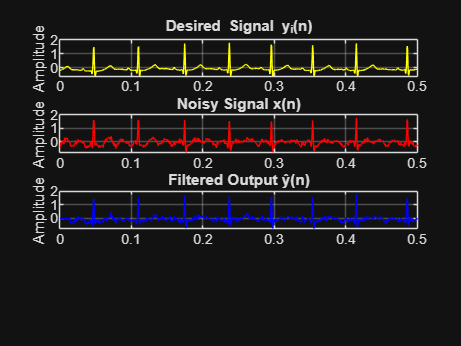


y_hat = zeros(N1,1); 
e = zeros(N1,1);     % Error = Filtered output

for n = K:N1
    x_vec = r_n(n:-1:n-K+1);       % input vector [x(n), x(n-1), ...]
    y(n) = w'*x_vec;         % filter output
    e(n) = x(n)-y(n);     % error
    w = w + 2*mu*e(n)*x_vec;     % weight update
end


%% Absolute error
abs_err = abs(s - e);

figure;
subplot(4,1,1);
plot(t, s, 'y','LineWidth',0.2); grid on;
title('Desired Signal y_i(n)'); ylabel('Amplitude');
xlim([0 0.5])

subplot(4,1,2);
plot(t, x, 'r'); grid on;
title('Noisy Signal x(n)'); ylabel('Amplitude');
xlim([0 0.5])

subplot(4,1,3);
plot(t, e, 'b','LineWidth',0.2); grid on;
title('Filtered Output ŷ(n)'); ylabel('Amplitude');
xlim([0 0.5])